pr=8

pr = 8

syms J
J=solve((pr.^2-4.^2)*J-30000==0)

$$J = 625$$

J=double(J)

J = 625

%qg=J*(pr.^2-pwf.^2)
qg=0:1:40000;
pwf=sqrt(pr.^2-(qg/J))

pwf =     8.0000    7.9999    7.9998    7.9997    7.9996    7.9995    7.9994    7.9993    7.9992    7.9991    7.9990    7.9989    7.9988    7.9987    7.9986    7.9985    7.9984    7.9983    7.9982    7.9981    7.9980    7.9979    7.9978    7.9977    7.9976    7.9975    7.9974    7.9973    7.9972    7.9971    7.9970    7.9969    7.9968    7.9967    7.9966    7.9965    7.9964    7.9963    7.9962    7.9961    7.9960    7.9959    7.9958    7.9957    7.9956    7.9955    7.9954    7.9953    7.9952    7.9951


qg000=0:100:40000

qg000 =            0         100         200         300         400         500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800        1900        2000        2100        2200        2300        2400        2500        2600        2700        2800        2900        3000        3100        3200        3300        3400        3500        3600        3700        3800        3900        4000        4100        4200        4300        4400        4500        4600        4700        4800        4900


pwf000=sqrt(pr.^2-(qg000/J))

pwf000 =     8.0000    7.9900    7.9800    7.9699    7.9599    7.9498    7.9398    7.9297    7.9196    7.9095    7.8994    7.8892    7.8791    7.8689    7.8588    7.8486    7.8384    7.8282    7.8179    7.8077    7.7974    7.7872    7.7769    7.7666    7.7563    7.7460    7.7356    7.7253    7.7149    7.7045    7.6942    7.6837    7.6733    7.6629    7.6525    7.6420    7.6315    7.6210    7.6105    7.6000    7.5895    7.5789    7.5684    7.5578    7.5472    7.5366    7.5260    7.5153    7.5047    7.4940



dt=0.0506

dt = 0.0506

dc=0.1143

dc = 0.1143

At=pi/4*dt.^2

At = 0.0020

Ac=pi/4*dc.^2-pi/4*dt.^2

Ac = 0.0082

%B=At/(At+Ac)%油管截面积占总截面积比
B=0.1

B = 0.1000

D=3197.2

D = 3.1972e+03

lc=3120

lc = 3120

rou=1000

rou = 1000

g=9.8

g = 9.8000

ptmin=2

ptmin = 2

hl=1/At

hl = 497.2893

p1h=rou*g*hl/(10.^6)

p1h = 4.8734


%----------液柱摩阻p1f------------------------
%摩擦阻力系数lambda
upu=input('柱塞上行速度为：');
Re=rou*upu*dt/0.000406

Re = 4.9852e+05

lambda=0.0032+0.221/Re.^0.237 %层流区的算法 ???有湍流（工程流体力学p171）

lambda = 0.0131

%柱塞上行速度取值为：upu1

p1f=lambda*(upu.^2/(2*dt)*rou)*hl/(10.^6)

p1f = 1.0271


%--------------pp柱塞重量取5.1kg  取自宁碧论文--------------------------
pp=5.1*g/At/(10.^6)

pp = 0.0249


% p1h为举升1方液柱的静夜柱压力，Mpa/方
% p1f为举升1方液柱的摩阻压力，Mpa/方
% w为每周期液体段塞体积，立方米

qg1=0:40000;
GLR=7500

GLR = 7500

T=input('柱塞每天运行次数为：')%注意迭代

T = 9

w=qg1/(GLR*T)       

w =          0    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007




ulup=qg1/(86400*GLR*At) %液体全进入油管的液柱上升速度

ulup =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


tpr=lc/upu

tpr = 780

%pL1=ulup*tpr*rou*g/(10.^6)
pL=(D-lc)*rou*g/(10.^6)

pL = 0.7566

k=10210.8

k = 1.0211e+04

pcmin=(ptmin+(p1h+p1f)*w+pp+pL)*(1+lc/k) %最小套压

pcmin =     3.6313    3.6314    3.6315    3.6316    3.6318    3.6319    3.6320    3.6321    3.6322    3.6323    3.6324    3.6326    3.6327    3.6328    3.6329    3.6330    3.6331    3.6332    3.6334    3.6335    3.6336    3.6337    3.6338    3.6339    3.6340    3.6342    3.6343    3.6344    3.6345    3.6346    3.6347    3.6348    3.6350    3.6351    3.6352    3.6353    3.6354    3.6355    3.6356    3.6358    3.6359    3.6360    3.6361    3.6362    3.6363    3.6364    3.6366    3.6367    3.6368    3.6369


pcmax=pcmin*(1+At/Ac)  %最大套压 At为油管截面积，Ac为套管截面积

pcmax =     4.5164    4.5166    4.5167    4.5168    4.5170    4.5171    4.5173    4.5174    4.5176    4.5177    4.5178    4.5180    4.5181    4.5183    4.5184    4.5186    4.5187    4.5188    4.5190    4.5191    4.5193    4.5194    4.5195    4.5197    4.5198    4.5200    4.5201    4.5203    4.5204    4.5205    4.5207    4.5208    4.5210    4.5211    4.5212    4.5214    4.5215    4.5217    4.5218    4.5220    4.5221    4.5222    4.5224    4.5225    4.5227    4.5228    4.5230    4.5231    4.5232    4.5234


pcp=(pcmin+pcmax)/2

pcp =     4.0739    4.0740    4.0741    4.0742    4.0744    4.0745    4.0746    4.0748    4.0749    4.0750    4.0751    4.0753    4.0754    4.0755    4.0757    4.0758    4.0759    4.0760    4.0762    4.0763    4.0764    4.0765    4.0767    4.0768    4.0769    4.0771    4.0772    4.0773    4.0774    4.0776    4.0777    4.0778    4.0780    4.0781    4.0782    4.0783    4.0785    4.0786    4.0787    4.0789    4.0790    4.0791    4.0792    4.0794    4.0795    4.0796    4.0798    4.0799    4.0800    4.0801


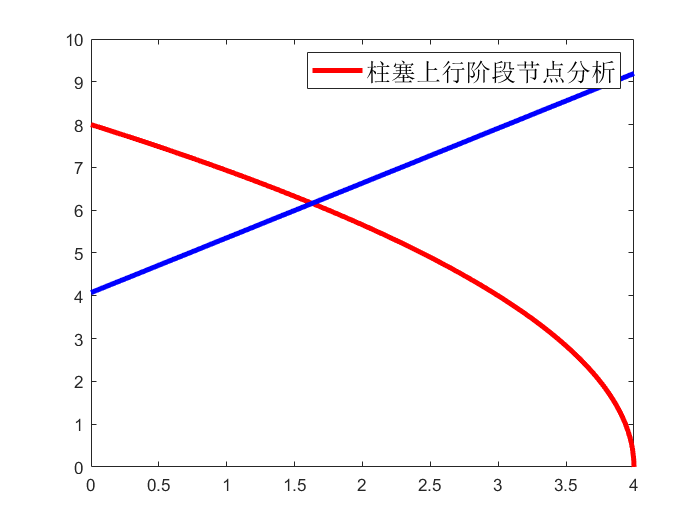


title("IPR曲线图",'fontsize',15)
xlabel("日产气量 万方/天",'FontSize',15)
ylabel('压力 MPa','FontSize',15)
plot(qg/10000,pwf,'-r',qg1/10000,pcp,'-b','linewidth',3) %算式原因，出现虚数，real()只画实部
legend('柱塞上行阶段节点分析','FontSize',15)



qg10=find(abs(pwf-pcp)<=0.01)%找出交点,即为协调产量

qg10 =        16251       16252       16253       16254       16255       16256       16257       16258       16259       16260       16261       16262       16263       16264       16265       16266       16267       16268       16269       16270       16271       16272       16273       16274       16275       16276       16277       16278       16279       16280       16281       16282       16283       16284       16285       16286       16287       16288       16289       16290       16291       16292       16293       16294       16295       16296       16297       16298       16299       16300


qg10=qg10(1,1)

qg10 = 16251


w1=qg10/(GLR*T) 

w1 = 0.2408

hup=hl*w1%单周期举升液柱高度

hup = 119.7252

pcmin1=(ptmin+(p1h+p1f)*w1+pp+pL)*(1+lc/k) %最小套压

pcmin1 = 5.4860

pcmax1=pcmin1*(1+At/Ac)  %最大套压 At为油管截面积，Ac为套管截面积

pcmax1 = 6.8232

pcp1=(pcmin1+pcmax1)/2

pcp1 = 6.1546


tpr=lc/upu 

tpr = 780

ql10=qg10/GLR %上升阶段协调产量对应产液量

ql10 = 2.1668

hL10=(ql10/86400)/At*tpr %柱塞上行后井底积液高度（假设全部进入油管，因为环空排气，液体不好进）

hL10 = 9.7277


t=25+273.15+lc/100*2.2*(1/2) 

t = 332.4700

tps=input("柱塞在井口停留时间:") 

tps = 4200

z=0.7

z = 0.7000

roug=29.449%(四兆帕下的密度）

roug = 29.4490

qg2=qg10

qg2 = 16251

upug=((qg2/40.35)/86400)/At %40.35为地面和井筒状态下体积比。

upug = 2.3181

Reg=upug*dt/(4.4545*10.^(-7))

Reg = 2.6332e+05

lambda=0.0032+0.221/Re.^0.237 

lambda = 0.0131

pfg=lambda*(upug.^2/(2*dt)*roug)*lc/(10.^6) %上行时气体摩阻pfg

pfg = 0.0637


pg=roug*g*lc/10.^6%气体柱摩阻

pg = 0.9004

step=600

step = 600

zx=tps/step;
qgt2(zx)=0;
qlt2(zx)=0;
pl2(zx+1)=0;
pc2(zx+1)=0;
qg2(zx+1)=0;
hl2(zx+1)=0;
qg2(1)=qg10;
hl2=0

hl2 = 0

for i=1:1:zx;
    
    qgt2(i)=qg2(i)*0.7;%油管产气量(本来比例为0.2，油管液面上升地多，修正地大一些）
                    %qgc2=qg2-qgt2    %油套环空产气量
    qlt2(i)=qgt2(i)/GLR; %油管液体产量
                     %qlc2=qgc2/GLR %环空液体产量
    hl2(i+1)=hl2(i)+qlt2(i)/(86400*At)*step;   
    pl2(i)=rou*g*hL10/10.^6+rou*g*hl2(i+1)/10.^6;
    pc2(i)=ptmin+pfg+pl2(i)+pL+pg;
    qg2(i+1)=J*(pr.^2-pc2(i).^2);
    
   
end


qg22=qg2(1,2:zx+1)%该阶段排出第一位产气

qg22 = 	1.0e+04 *

    3.0652    3.0178    2.9700    2.9219    2.8734    2.8247    2.7759


qg22zong=sum(qg22/86400*step,2) %矩阵行求和 该阶段中产气量（立方米）

qg22zong = 1.4201e+03

hl22=hl2(1,2:zx+1)+hL10 %每10分钟的积液高度

hl22 =    14.9656   24.8453   34.5723   44.1451   53.5628   62.8242   71.9288


hl2zong=hl22(end)%二阶段末态积液高度

hl2zong = 71.9288

pc22=pc2(1,1:zx)%二阶段正常井底压力

pc22 =     3.8674    3.9642    4.0595    4.1533    4.2456    4.3364    4.4256


pl22=pl2(1,2:zx+1)%二阶段正常液柱压力

pl22 =     0.2435    0.3388    0.4326    0.5249    0.6157    0.7049         0


pc3=pc22(end)%二阶段末态井底压力

pc3 = 4.4256

qg22mo=qg22(end) %二阶段最后一个十分钟的产气量（立方米每天）

qg22mo = 2.7759e+04

qlc2zong=qg22zong*(1-0.7)/GLR%二阶段末态环空液体量

qlc2zong = 0.0568

hlc2zong=qlc2zong/Ac%二阶段末态环空液柱高度

hlc2zong = 6.8852

qgc2zong=qg22zong*(1-0.7)%二阶段末态环空气体体积（立方米）

qgc2zong = 426.0184

roug=0.75

roug = 0.7500

mc2=qgc2zong*roug %认为进入套管的气体也排出了

mc2 = 319.5138

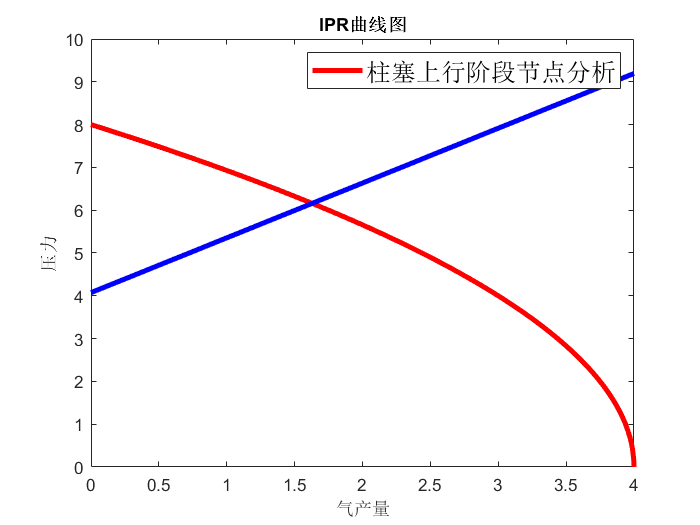

title("IPR曲线图")
xlabel("气产量")
ylabel('压力')

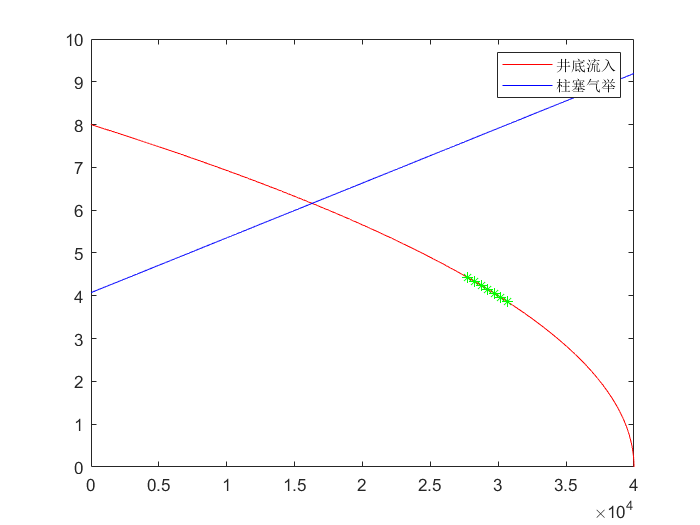

plot(qg,pwf,'-r',qg1,pcp,'-b',qg22,pc22,"g*") %算式原因，出现虚数，real()只画实部
legend('井底流入','柱塞气举')


%xlswrite('C:\Users\DELL\Desktop\mat.file\data1.xlsx',pc2,1,"B2") %t11时间
%xlswrite('C:\Users\DELL\Desktop\mat.file\data1.xlsx',qg22,1,"B3") %套压
%xlswrite('C:\Users\DELL\Desktop\mat.file\data1.xlsx',hl22,1,"B4") %油压


z=0.7%气体修正系数

z = 0.7000

M=17.18%天然气相对分子质量

M = 17.1800

Rg=483.93

Rg = 483.9300

updg=input("柱塞在气体中下行速度:") %60-150m/min，取120m/min，即2m/s

updg = 2

updl=input("柱塞在液体中下行速度:") %15-40m/min，取30m/min，即0.5m/s

updl = 0.5000

tpdg=(lc-hl2zong)/updg%柱塞在空气中下行时间

tpdg = 1.5240e+03

tpdl=hl2zong/updl%柱塞在液体中下行时间

tpdl = 143.8576

tpd=tpdg+tpdl;%总下行时间
tpd=round(tpd/100)*100

tpd = 1700

step3=100;
roug=0.75

roug = 0.7500

qg3=qg22mo%承接二阶段的产气量，作为三阶段的起始产气量（立方米每天）

qg3 = 2.7759e+04

pt=ptmin%三阶段起始油压为最小油压

pt = 2

zy=tpd/step3;
qgt3(zy+1)=0;
qlt3(zy+1)=0;
pl3(zy+1)=0;
qg3(zy+1)=0;
hl3(zy+1)=0;
pt(zy+1)=0;
qg3(1)=qg22mo;
hl3=hl2zong %三阶段初始高度为二阶段末态高度

hl3 = 71.9288

for i=1:1:zy;
    
    qgt3(i)=qg3(i)*0.3;%油管产气量(关井柱塞下落，流体进入油管、环空比例0.5，较0.7减少）
                    %qgc2=qg2-qgt2    %油套环空产气量
    qlt3(i)=qgt3(i)/GLR; %油管液体产量
                     %qlc2=qgc2/GLR %环空液体产量
    hl3(i+1)=hl3(i)+qlt3(i)/(86400*At)*step3; 
    pt(i+1)=pt(i)+qgt3(i)/86400*step3*roug*Rg*t*z/((lc-hl2zong)*At*10.^6);
    pl3(i)=rou*g*hl3(i+1)/10.^6;
    pc3(i)=pt(i+1)+pl3(i)+pL+pp+pg;
    qg3(i+1)=J*(pr.^2-pc3(i).^2);
%    
end

qg33=qg3(1,2:zy+1)%该阶段去掉第一位产气

qg33 = 	1.0e+04 *

    2.7198    2.6415    2.5633    2.4853    2.4077    2.3307    2.2544    2.1790    2.1046    2.0313    1.9592    1.8885    1.8192    1.7514    1.6851    1.6204    1.5574


pt33=pt(1,2:zy+1)%三阶段去掉第一位油压

pt33 =     2.1328    2.2630    2.3894    2.5120    2.6309    2.7462    2.8577    2.9656    3.0698    3.1705    3.2677    3.3615    3.4518    3.5389    3.6227    3.7033    3.7809


qg33zong=sum(qg33/86400*step3,2) %矩阵行求和 该阶段中产气量（立方米）

qg33zong = 416.6504

hl33=hl3(1,2:zy+1) %每10分钟的积液高度

hl33 =    72.5679   73.1941   73.8022   74.3923   74.9645   75.5189   76.0554   76.5745   77.0761   77.5606   78.0283   78.4793   78.9141   79.3330   79.7362   80.1241   80.4972


hl3zong=hl33(end)%三阶段末态积液高度

hl3zong = 80.4972

pc3mo=pc3(end)%三阶段末态井底压力

pc3mo = 6.2516

qg33mo=qg33(end) %三阶段最后一个步长的产气量（立方米每天）

qg33mo = 1.5574e+04

pt33mo=pt33(end)

pt33mo = 3.7809

qlc3zong=qg33zong*(1-0.3)/GLR%三阶段末态环空液体量

qlc3zong = 0.0389

qgc3zong=qg33zong*(1-0.3)%三阶段末态环空气体量（体积）

qgc3zong = 291.6553


mc3=qgc3zong*roug%三阶段环空气体质量

mc3 = 218.7414

pccmo=(pcmin1)+z*mc3*Rg*t/(lc*Ac*10.^6)

pccmo = 6.4431

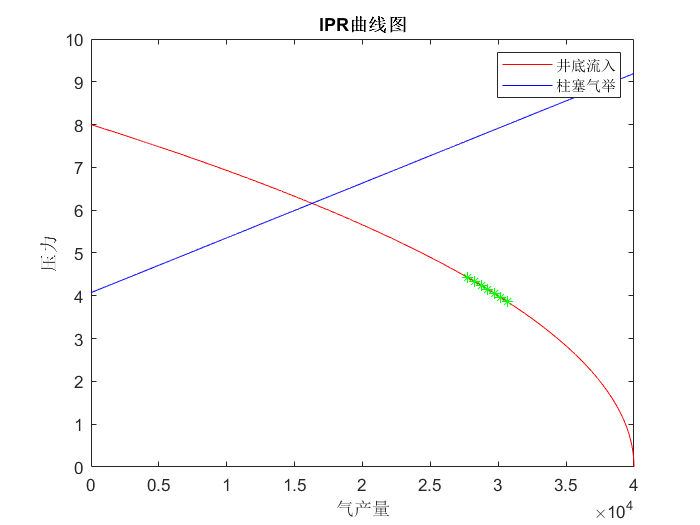


title("IPR曲线图")
xlabel("气产量")
ylabel('压力')

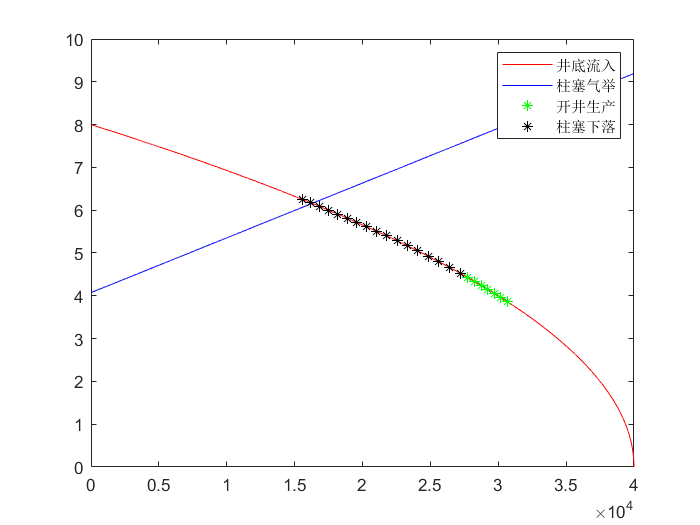

plot(qg,pwf,'-r',qg1,pcp,'-b',qg22,pc22,"g*",qg33,pc3,"k*") %算式原因，出现虚数，real()只画实部
legend('井底流入','柱塞气举',"开井生产","柱塞下落")


xlswrite('C:\Users\DELL\Desktop\mat.file\data1.xlsx',qg33,2,"B2") %三阶段产量
xlswrite('C:\Users\DELL\Desktop\mat.file\data1.xlsx',pc3,2,"B3") %三阶段井底压力
xlswrite('C:\Users\DELL\Desktop\mat.file\data1.xlsx',pt33,2,"B4") %三阶段油压
xlswrite('C:\Users\DELL\Desktop\mat.file\data1.xlsx',hl33,2,"B5") %三阶段液柱高度

step4=120;
roug=0.75

roug = 0.7500

%承接三阶段的产气量，作为四阶段的起始产气量（立方米每天）
zz=100

zz = 100

pt4(zz)=0;
pt4=pt33mo%四阶段起始油压为三阶段末态油压

pt4 = 3.7809

qg4(zz)=0;
qg4(1)=qg33mo;
hl4(zz)=0;
hl4(1)=hl3zong;
pc4(zz)=0;
pc4(1)=pc3mo;
pcc4(zz)=0;
pcc4=pccmo-1.1;

pcmax4(zz)=0;
pcmax4(1)=(ptmin+(p1h+p1f)*hl3zong*At+pp+pL)*(1+lc/k)*(1+At/Ac);

for i=1:1:zz;
    qgt4(i)=qg4(i)*B;%关井恢复后仅有0.1的流体进入油管               
    qlt4(i)=qgt4(i)/GLR; %油管液体产量                 
    hl4(i+1)=hl4(i)+qlt4(i)/(86400*At)*step4; 
    pt4(i+1)=pt4(i)+qgt4(i)/86400*step4*roug*Rg*t*z/((lc-hl3zong)*At*10.^6);
    pl4(i)=rou*g*hl4(i+1)/10.^6;
    pc4(i)=pt4(i+1)+pl4(i)+pL+pp+pg;%井底流压
    qg4(i+1)=J*(pr.^2-pc4(i).^2);
    pcmax4(i+1)=(ptmin+(p1h+p1f)*hl4(i+1)*At+pp+pL)*(1+lc/k)*(1+At/Ac);
    pcc4(i+1)=pcc4(i)+qg4(i)*(1-B)/86400*step4*roug*Rg*t*z/(lc*Ac*10.^6);%套压
    if pcc4(i+1)>pcmax4(i+1)*1.03
          break
          
    end 
end 
n=length(pcc4(:))%该过程计算次数  

n = 18

tpc=step4*n%压力恢复时间

tpc = 2160

hl4end=hl4(n)

hl4end = 82.6451

pwf4=pc4(1:n-1)

pwf4 =     6.2829    6.3137    6.3440    6.3738    6.4032    6.4321    6.4605    6.4885    6.5160    6.5430    6.5696    6.5958    6.6216    6.6469    6.6718    6.6962    6.7203


qg44=qg4(1:n-1)

qg44 = 	1.0e+04 *

    1.5574    1.5328    1.5086    1.4846    1.4609    1.4374    1.4143    1.3914    1.3687    1.3464    1.3243    1.3025    1.2810    1.2597    1.2387    1.2180    1.1975


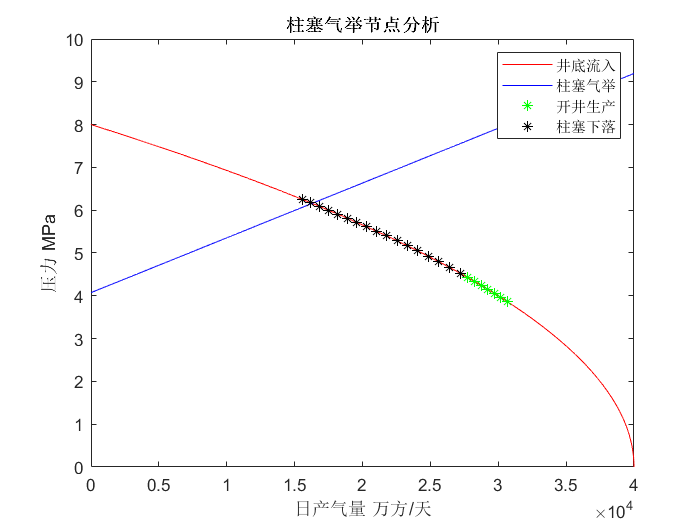

title("柱塞气举节点分析")
xlabel("日产气量 万方/天")
ylabel('压力 MPa')

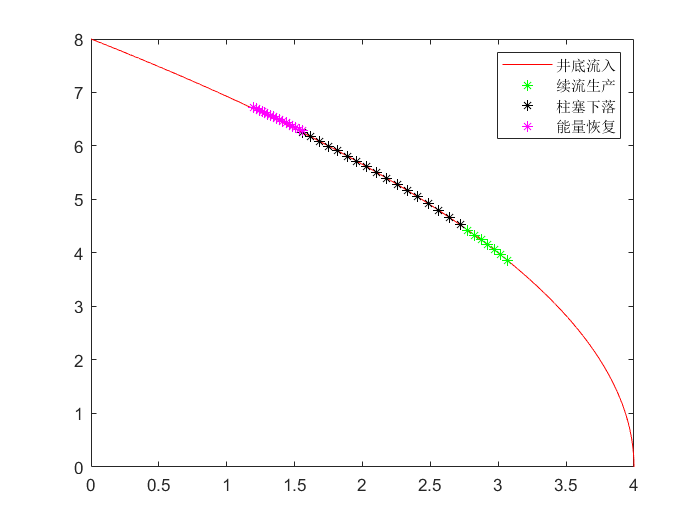

plot(qg/10000,pwf,'-r',qg22/10000,pc22,"g*",qg33/10000,pc3,"k*",qg44/10000,pwf4,"m*") %算式原因，出现虚数，real()只画实部
legend('井底流入',"续流生产","柱塞下落","能量恢复")

qfang=(pt4(n)-ptmin)*10.^6*(lc-hl4(end))*At/(z*Rg*t)/0.75

qfang = 165.5281

tzong=tpr+tps+tpd+tpc

tzong = 8840

tkai=(tpr+tps)/60

tkai = 83

tguan=(tpd+tpc)/60

tguan = 64.3333

pcjingdi=pcc4(end)

pcjingdi = 6.2998

pcjingkou=(ptmin+(p1h+p1f)*hl4end*At+pp+pL)*(1+lc/k)

pcjingkou = 4.9116

np=86400/tzong

np = 9.7738

Ql=np*At*hl4end

Ql = 1.6243

Qg=Ql*GLR

Qg = 1.2182e+04

Qfang=(qfang+qg22zong)*np

Qfang = 1.5497e+04

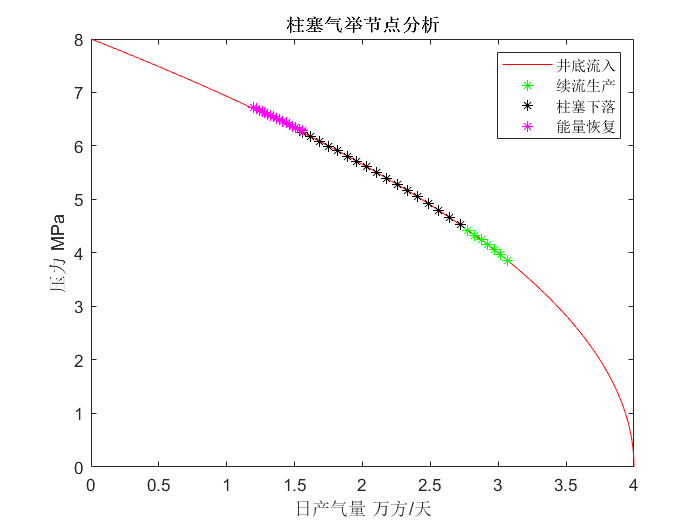


title("柱塞气举节点分析")
xlabel("日产气量 万方/天")
ylabel('压力 MPa')

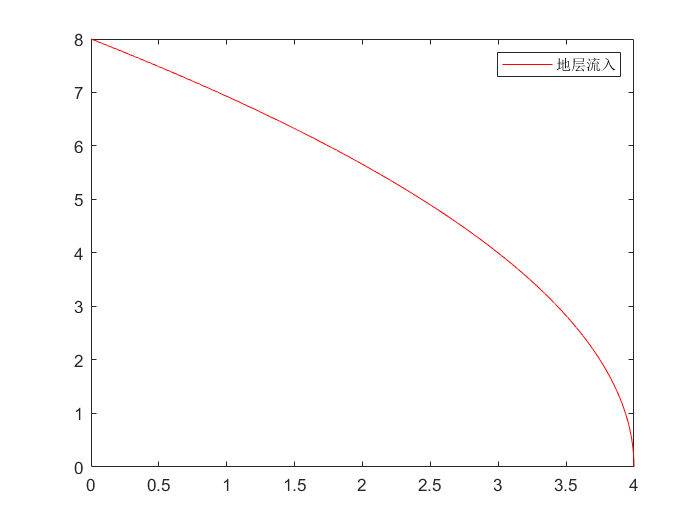

plot(qg/10000,pwf,'-r') %算式原因，出现虚数，real()只画实部
legend('地层流入')

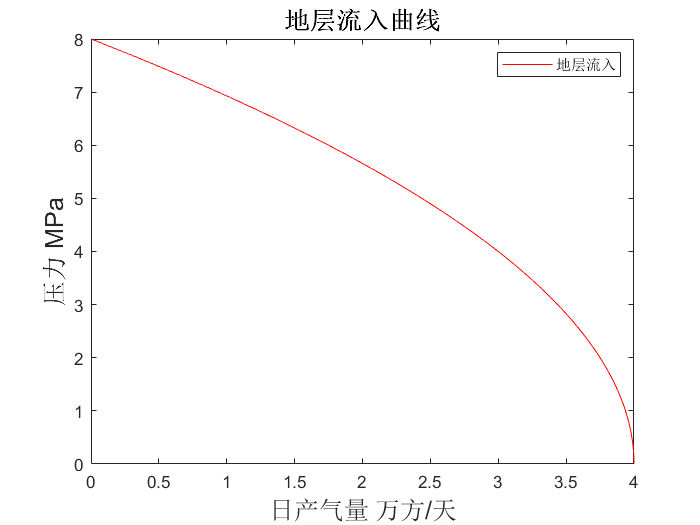

title("地层流入曲线",'FontSize',15)
xlabel("日产气量 万方/天",'FontSize',15)
ylabel('压力 MPa','FontSize',15)

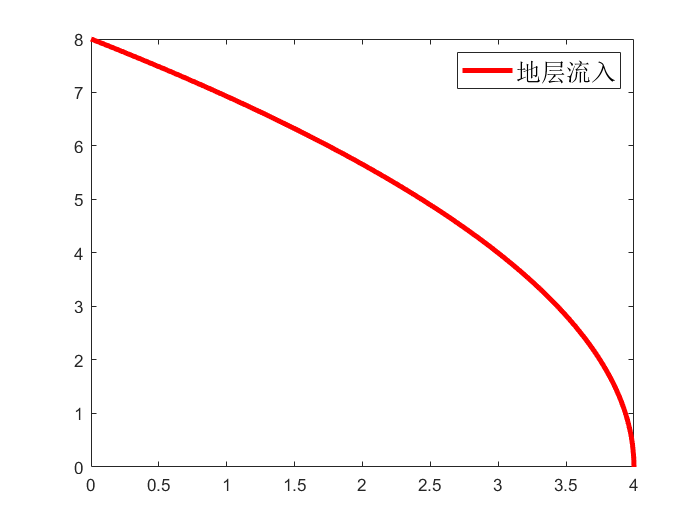

plot(qg/10000,pwf,'-r','linewidth',3) %算式原因，出现虚数，real()只画实部
legend('地层流入','FontSize',15)

%title("柱塞上行阶段节点分析",'FontSize',15)
qg111=qg1(8000:100:19000)

qg111 =         7999        8099        8199        8299        8399        8499        8599        8699        8799        8899        8999        9099        9199        9299        9399        9499        9599        9699        9799        9899        9999       10099       10199       10299       10399       10499       10599       10699       10799       10899       10999       11099       11199       11299       11399       11499       11599       11699       11799       11899       11999       12099       12199       12299       12399       12499       12599       12699       12799       12899


pcp111=pcp(8000:100:19000)

pcp111 =     5.0980    5.1108    5.1236    5.1364    5.1492    5.1620    5.1748    5.1876    5.2004    5.2132    5.2260    5.2389    5.2517    5.2645    5.2773    5.2901    5.3029    5.3157    5.3285    5.3413    5.3541    5.3669    5.3797    5.3925    5.4053    5.4181    5.4309    5.4437    5.4565    5.4693    5.4821    5.4949    5.5077    5.5205    5.5333    5.5461    5.5589    5.5717    5.5845    5.5973    5.6102    5.6230    5.6358    5.6486    5.6614    5.6742    5.6870    5.6998    5.7126    5.7254


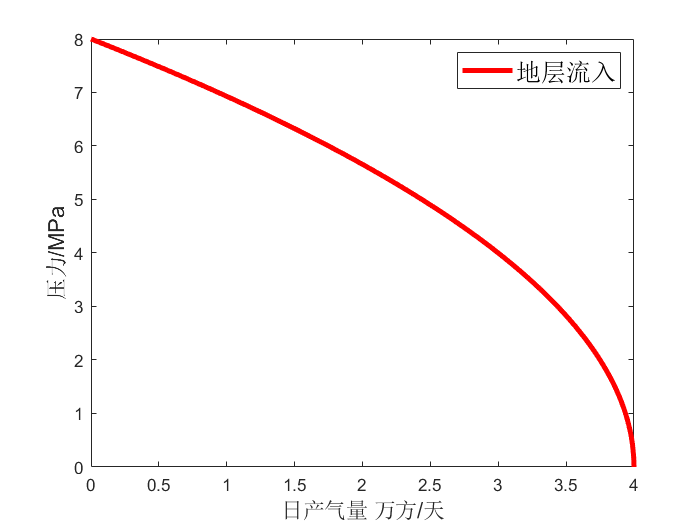

xlabel("日产气量 万方/天",'FontSize',13)
ylabel('压力/MPa','FontSize',13)

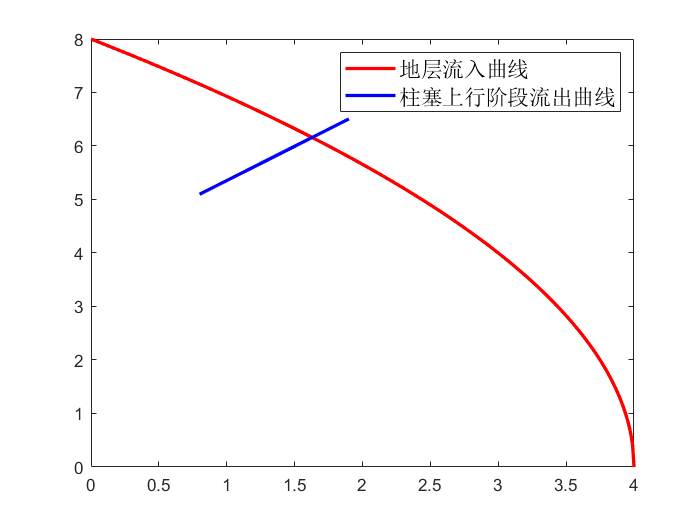

plot(qg000/10000,pwf000,'-r',qg111/10000,pcp111,'-b','linewidth',2) %算式原因，出现虚数，real()只画实部
legend('地层流入曲线',"柱塞上行阶段流出曲线",'FontSize',13)

xx=1:0.5:3.5

xx =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000


yy=(1/(2.95))*xx+3

yy =     3.3390    3.5085    3.6780    3.8475    4.0169    4.1864


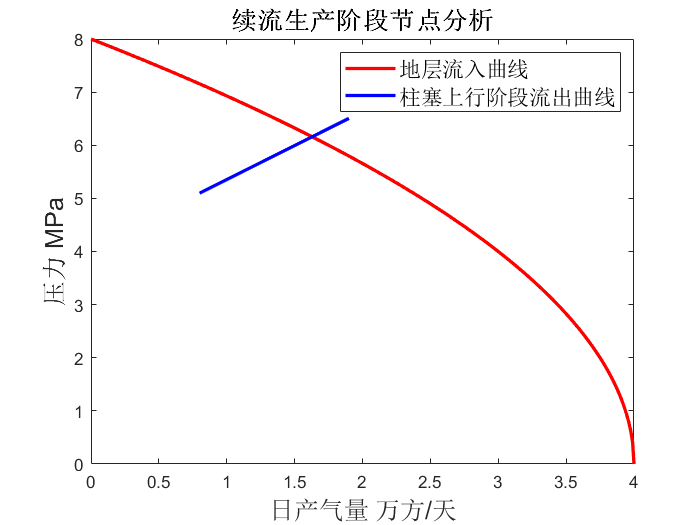

title("续流生产阶段节点分析",'FontSize',15)
xlabel("日产气量 万方/天",'FontSize',15)
ylabel('压力 MPa','FontSize',15)

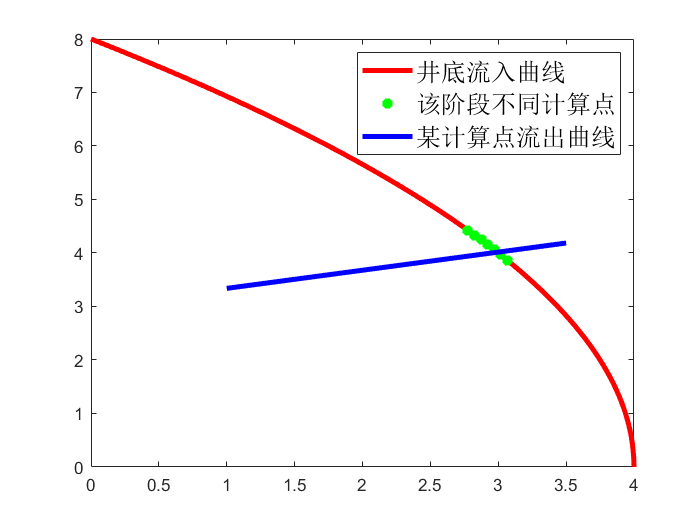

plot(qg/10000,pwf,'-r',qg22/10000,pc22,"g*",xx,yy,'-b','linewidth',3) %算式原因，出现虚数，real()只画实部
legend('井底流入曲线','该阶段不同计算点',"某计算点流出曲线",'FontSize',15)

xx3=1:0.5:3.5

xx3 =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000


yy3=[5,5,5,5,5,5]

yy3 =      5     5     5     5     5     5


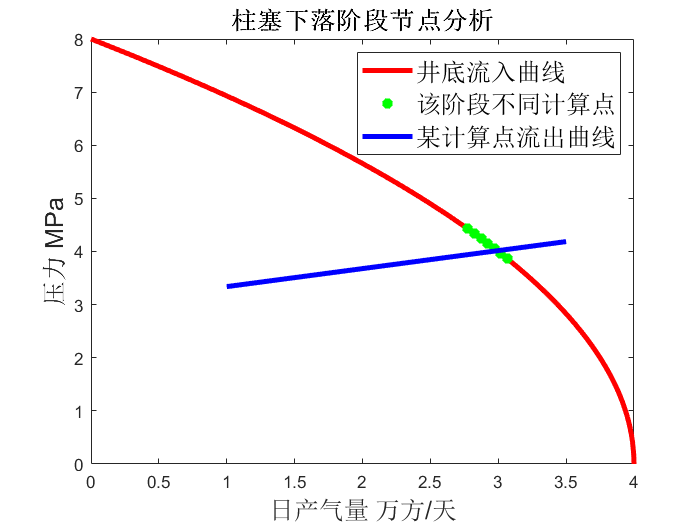

title("柱塞下落阶段节点分析",'FontSize',15)
xlabel("日产气量 万方/天",'FontSize',15)
ylabel('压力 MPa','FontSize',15)

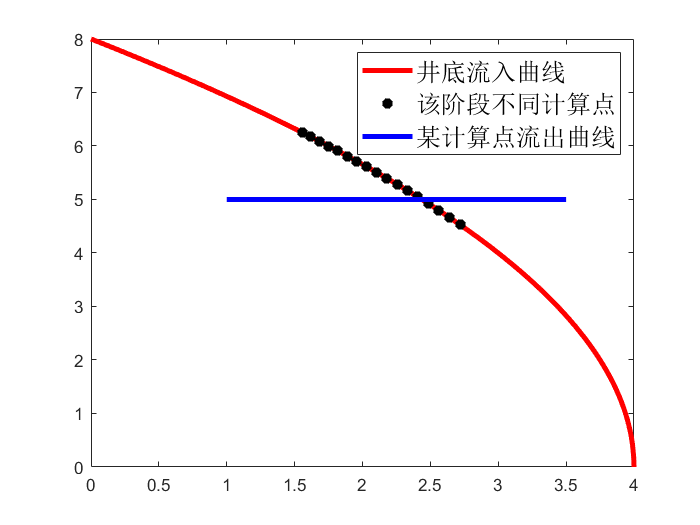

plot(qg/10000,pwf,'-r',qg33/10000,pc3,"k*",xx3,yy3,'-b','linewidth',3) %算式原因，出现虚数，real()只画实部
legend('井底流入曲线','该阶段不同计算点',"某计算点流出曲线",'FontSize',15)

xx3=0.6:0.2:1.8

xx3 =     0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000


yy3=[6.4,6.4,6.4,6.4,6.4,6.4,6.4]

yy3 =     6.4000    6.4000    6.4000    6.4000    6.4000    6.4000    6.4000


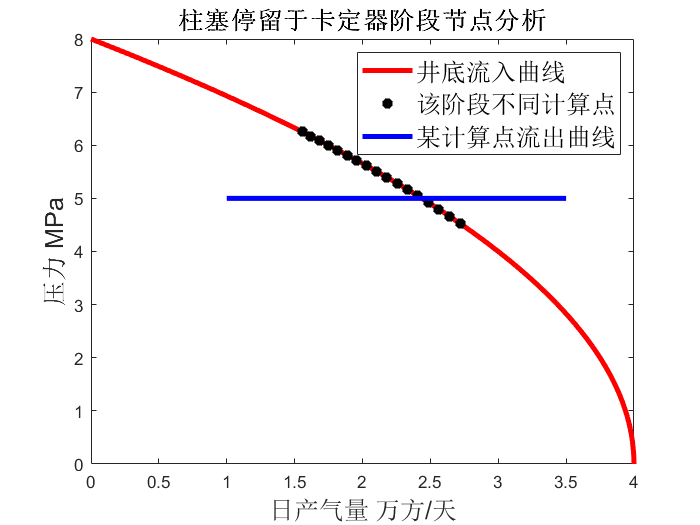

title("柱塞停留于卡定器阶段节点分析",'FontSize',15)
xlabel("日产气量 万方/天",'FontSize',15)
ylabel('压力 MPa','FontSize',15)

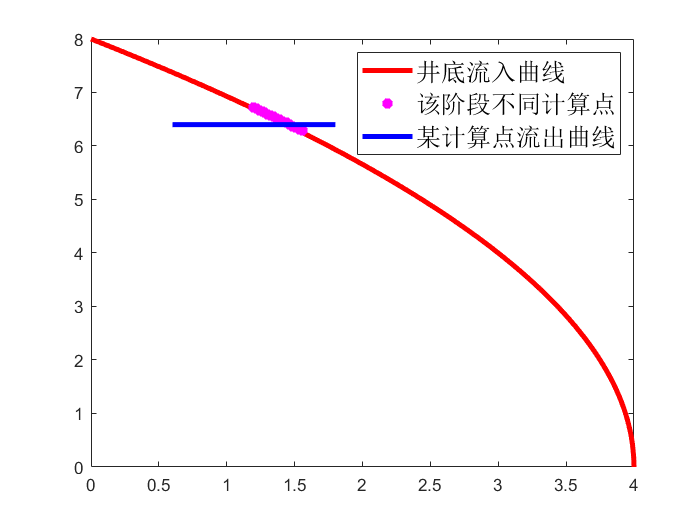

plot(qg/10000,pwf,'-r',qg44/10000,pwf4,"m*",xx3,yy3,'-b','linewidth',3) %算式原因，出现虚数，real()只画实部
legend('井底流入曲线','该阶段不同计算点',"某计算点流出曲线",'FontSize',15)

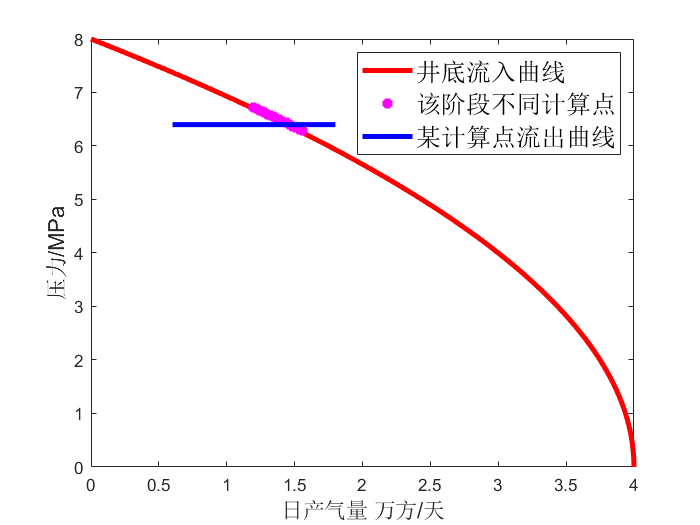

%title("后续三个阶段井底流压变化图",'FontSize',13)
xlabel("日产气量 万方/天",'FontSize',13)
ylabel('压力/MPa','FontSize',13)

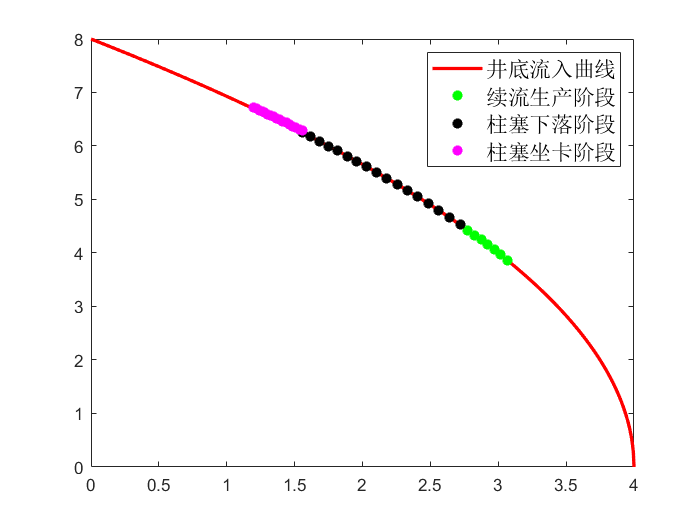

plot(qg000/10000,pwf000,'-r',qg22/10000,pc22,"g*",qg33/10000,pc3,"k*",qg44/10000,pwf4,"m*",'linewidth',2) %算式原因，出现虚数，real()只画实部
legend("井底流入曲线",'续流生产阶段',"柱塞下落阶段","柱塞坐卡阶段",'FontSize',13)